%% clear workspace
clear variables
close all
clc

## load in data

addpath(genpath('C:\Users\Xiangnan\Documents\MyGitRepo\FLImBrushDataProcessingTool\Preprocessing_APD'))
FB = load(['C:\Users\Xiangnan\Box Sync\FLImBrush vs V4\20210722V4vsFLImBRUSHDye\FLImBRUSH\20210722DyeTest2\' ...
    'Decon 10GS 154ns 0.9619 ref excluded DC front no moving avg 540-640\20210722DyeTest2_03.mat']);
FBCh3 = load(['C:\Users\Xiangnan\Box Sync\FLImBrush vs V4\20210722V4vsFLImBRUSHDye\FLImBRUSH\20210722DyeTest2\' ...
    'Decon 10GS 154ns 0.9619 ref excluded DC front no moving avg 540-640\20210722DyeTest2_05.mat']);
FBDC = load(['C:\Users\Xiangnan\Box Sync\FLImBrush vs V4\20210722V4vsFLImBRUSHDye\FLImBRUSH\20210722DyeTest2\' ...
    'Decon 10GS 154ns 0.9619 ref excluded DC front 540-640\20210722DyeTest2_03.mat']);
FBDCCh3 = load(['C:\Users\Xiangnan\Box Sync\FLImBrush vs V4\20210722V4vsFLImBRUSHDye\FLImBRUSH\20210722DyeTest2\' ...
    'Decon 10GS 154ns 0.9619 ref excluded DC front 540-640\20210722DyeTest2_05.mat']);

## plot irf

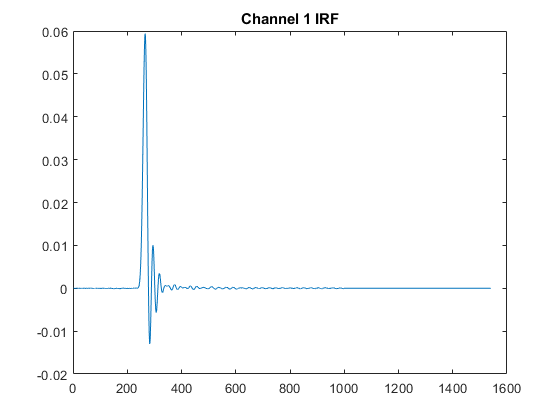

irf1 = FBDC.Ch1DataObj.APDObj.irfTNorm;
figure
plot(irf1(:,215));
title('Channel 1 IRF')

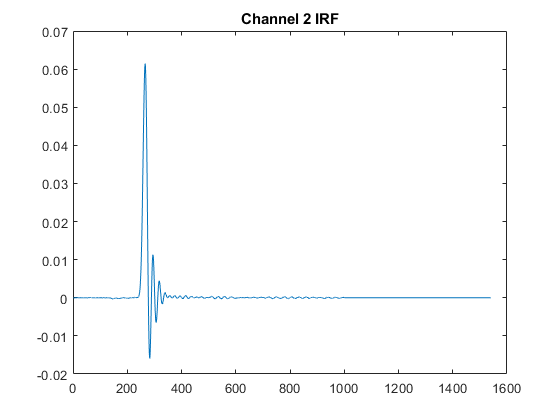


irf2 = FBDC.Ch2DataObj.APDObj.irfTNorm;
figure
plot(irf2(:,200));
title('Channel 2 IRF')

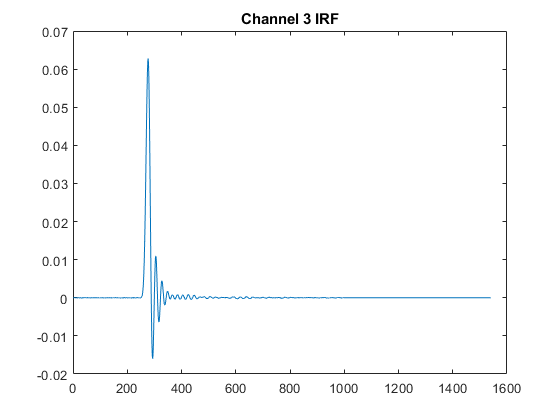


irf3 = FBDCCh3.Ch3DataObj.APDObj.irfTNorm;
figure
plot(irf3(:,211));
title('Channel 3 IRF')

## plot raw data

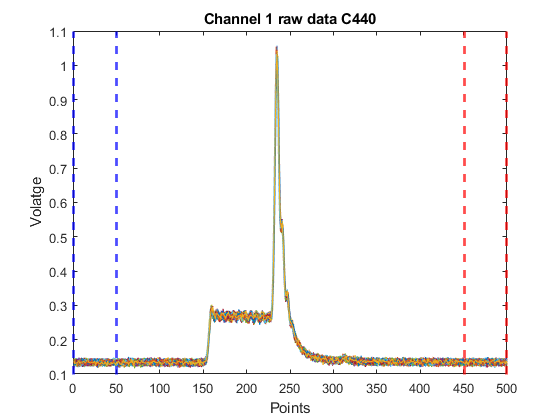


rawData1 = FBDC.Ch1DataObj.rawData;
figure;plot(rawData1)
xline(1,'b--','LineWidth',2)
xline(50,'b--','LineWidth',2)
xline(451,'r--','LineWidth',2)
xline(500,'r--','LineWidth',2)
title('Channel 1 raw data C440')
xlabel('Points')
ylabel('Volatge')

mean(mean(rawData1(1:50,:)))

ans = 0.1337

mean(mean(rawData1(451:500,:)))

ans = 0.1344

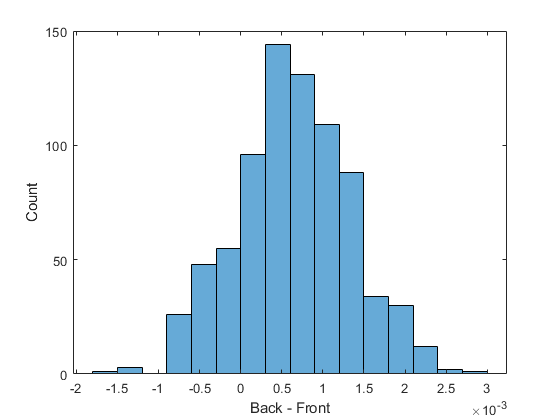

diff = mean(rawData1(451:500,:))-mean(rawData1(1:50,:));
figure
histogram(diff)
xlabel('Back - Front')
ylabel('Count')

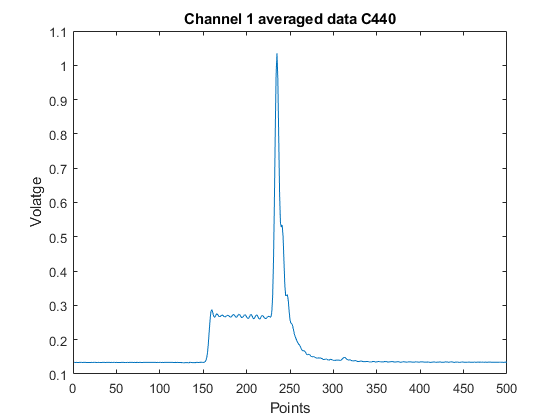

figure;plot(mean(rawData1,2))
title('Channel 1 averaged data C440')
xlabel('Points')
ylabel('Volatge')

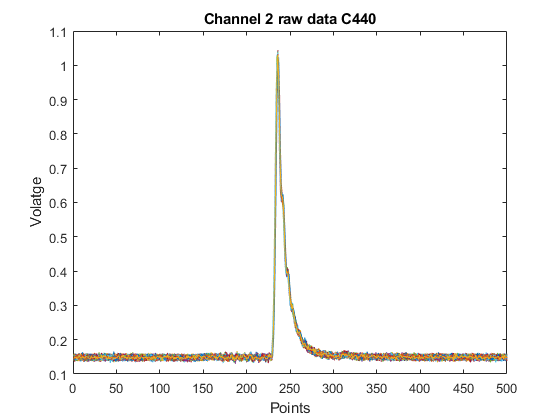

rawData2 = FBDC.Ch2DataObj.rawData;
figure;plot(rawData2)
title('Channel 2 raw data C440')
xlabel('Points')
ylabel('Volatge')

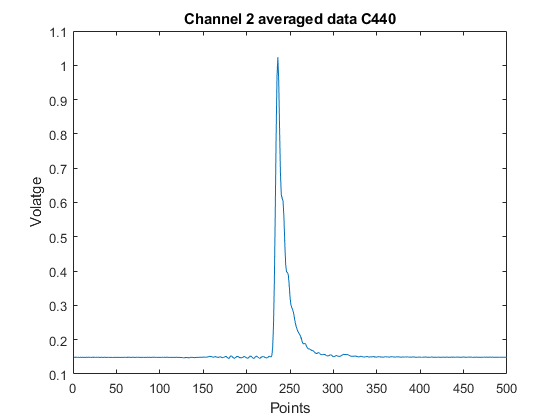

figure;plot(mean(rawData2,2))
title('Channel 2 averaged data C440')
xlabel('Points')
ylabel('Volatge')

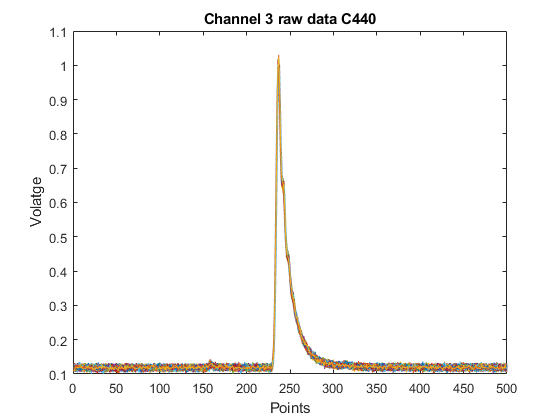

rawData3 = FBDCCh3.Ch3DataObj.rawData;
figure;plot(rawData3)
title('Channel 3 raw data C440')
xlabel('Points')
ylabel('Volatge')

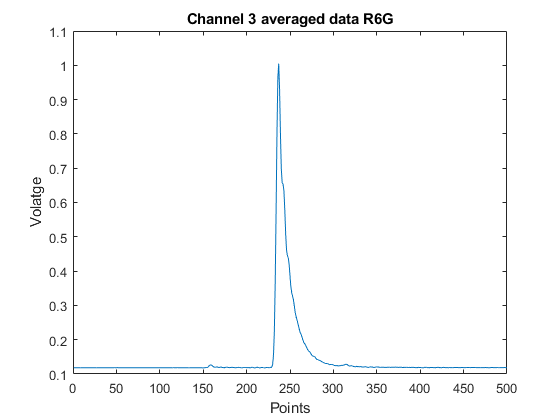

figure;plot(mean(rawData3,2))
title('Channel 3 averaged data R6G')
xlabel('Points')
ylabel('Volatge')

## lifetime violin

FBLT1 = FB.Ch1DataObj.LTs;
FBLT2 = FB.Ch2DataObj.LTs;
FBLT3 = FBCh3.Ch3DataObj.LTs;
FBDCLT1 = FBDC.Ch1DataObj.LTs;
FBDCLT2 = FBDC.Ch2DataObj.LTs;
FBDCLT3 = FBDCCh3.Ch3DataObj.LTs;
FBAll = [FBLT1 FBLT2 FBLT3(1:195)];
FBDCAll = [FBDCLT1 FBDCLT2 FBDCLT3(1:195)];


## plot

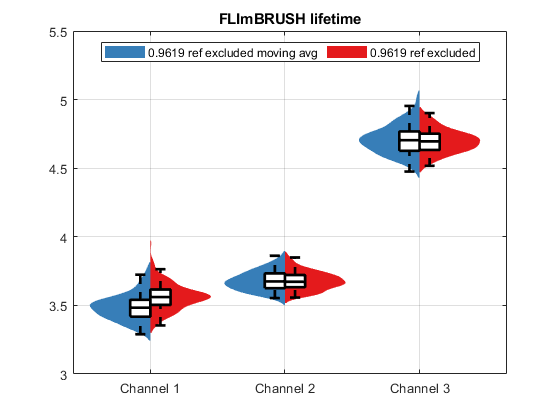

figure
violinbox(FBAll,FBDCAll,1,1,[])
grid on
ylim([3 5.5])
% yline(3.38)
legend('0.9619 ref excluded moving avg','0.9619 ref excluded')
title('FLImBRUSH lifetime')
xticklabels({'Channel 1','Channel 2','Channel 3'})

## plot channel 1 DC

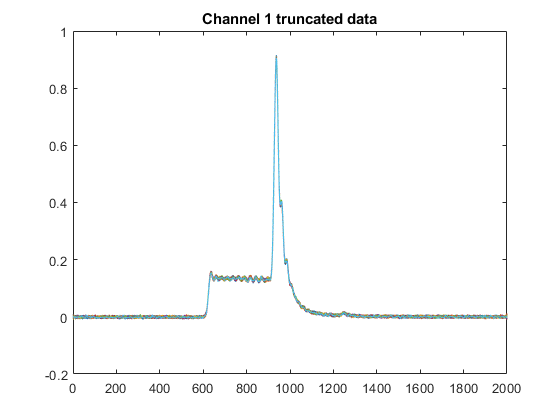

data1 = FB.Ch1DataObj.averagedData;
figure;plot(data1);title('Channel 1 truncated data')

% figure;plot(mean(data1,2));title('Channel 1 truncated data')
% figure;plot(mean(data1(1:200,:)))
% title('Channel 1 DC avg from start')
dataTemp1 = data1(1:100,:);
DC1 = mean(dataTemp1);
std(dataTemp1(:))

ans = 0.0019

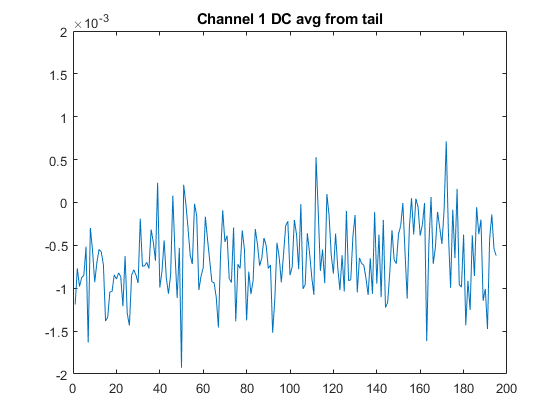

figure;plot(DC1);ylim([-0.002 0.002])
title('Channel 1 DC avg from tail')

mean(mean(dataTemp1))

ans = -6.4995e-04

## plot channel 1 DC moving avg

data11 = FBDC.Ch1DataObj.averagedData;
% figure;plot(data11);title('Channel 1 truncated data')
% figure;plot(mean(data11,2));title('Channel 1 truncated data')
% figure;plot(mean(data1(1:200,:)))
% title('Channel 1 DC avg from start')
dataTemp11 = data11(1:100,:);
DC11 = mean(dataTemp11);
std(dataTemp11(:))

ans = 0.0019

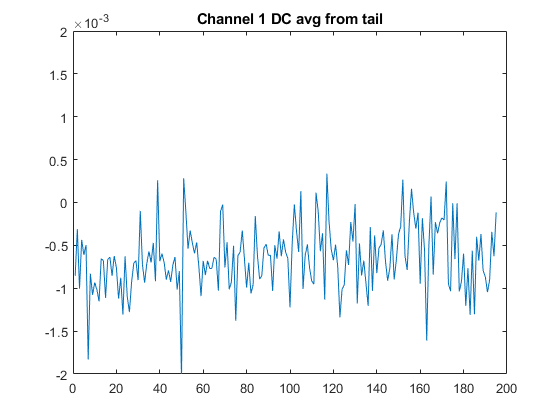

figure;plot(DC11);ylim([-0.002 0.002])
title('Channel 1 DC avg from tail')

mean(mean(dataTemp11))

ans = -6.4823e-04

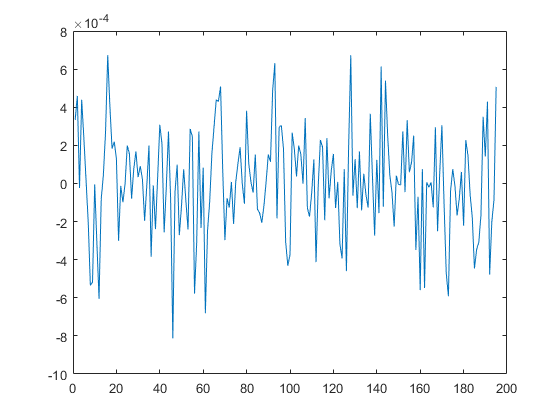

figure;plot(DC11-DC1)

## plot channel 2 DC

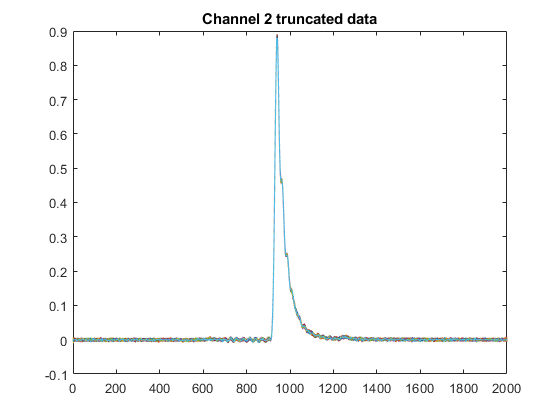

data2 = FB.Ch2DataObj.averagedData;
figure;plot(data2);title('Channel 2 truncated data')

% figure;plot(mean(data2,2));title('Channel 2 truncated data')
% figure;plot(mean(data2(1:200,:)))
% title('Channel 2 DC avg from start')
dataTemp2 = data2(end-30:end,:);
std(dataTemp2(:))

ans = 0.0017

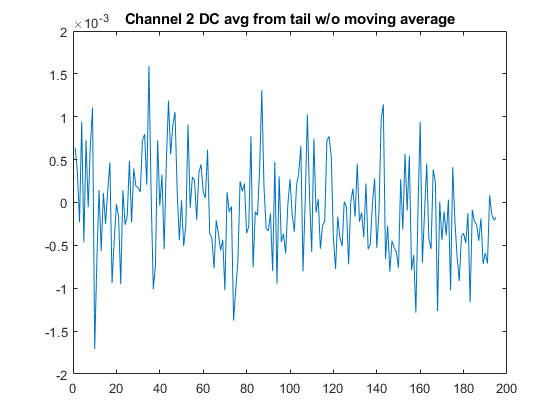

figure;plot(mean(dataTemp2));ylim([-0.002 0.002])
title('Channel 2 DC avg from tail w/o moving average')

mean(mean(dataTemp2))

ans = -8.8778e-05

## plot channel 2 DC moving average

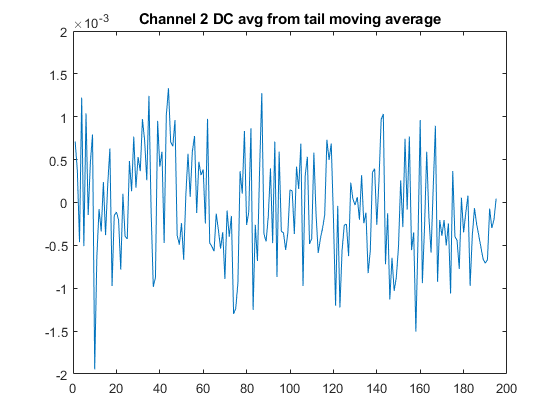

data22 = FBDC.Ch2DataObj.averagedData;
% figure;plot(data22);title('Channel 2 truncated data')
% figure;plot(mean(data22,2));title('Channel 2 truncated data')
% figure;plot(mean(data2(1:200,:)))
% title('Channel 2 DC avg from start')
dataTemp22 = data22(end-30:end,:);
figure;plot(mean(dataTemp22));ylim([-0.002 0.002])
title('Channel 2 DC avg from tail moving average')

mean(mean(dataTemp22))

ans = -8.4829e-05

## plot channel 3 DC

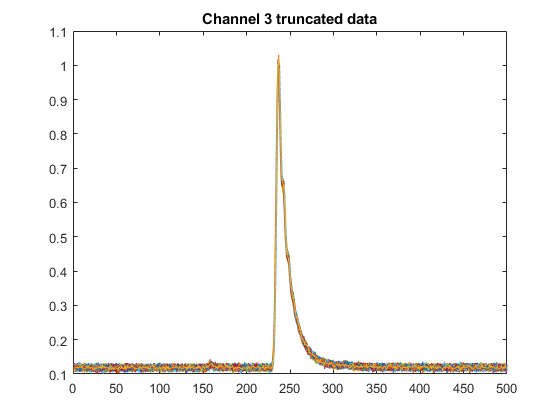

data3 = FBCh3.Ch3DataObj.rawData;
figure;plot(data3);title('Channel 3 truncated data')

% figure;plot(mean(data3,2));title('Channel 3 truncated data')
% figure;plot(mean(data2(1:200,:)))
% title('Channel 2 DC avg from start')
dataTemp3 = data3(1:100,:);
std(dataTemp3(:))

ans = 0.0036

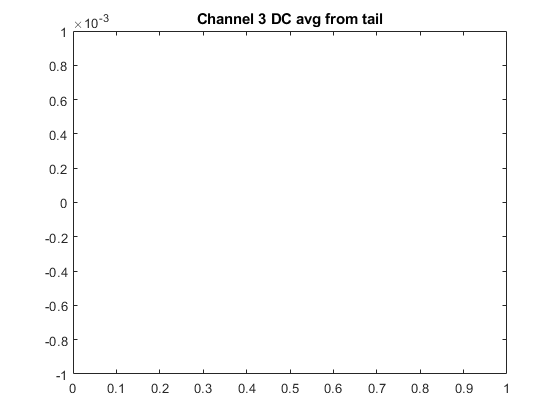

figure;plot(mean(dataTemp3));ylim([-0.001 0.001])
title('Channel 3 DC avg from tail')

mean(mean(dataTemp3))

ans = 0.1182

## plot channel 3 DC moving avg

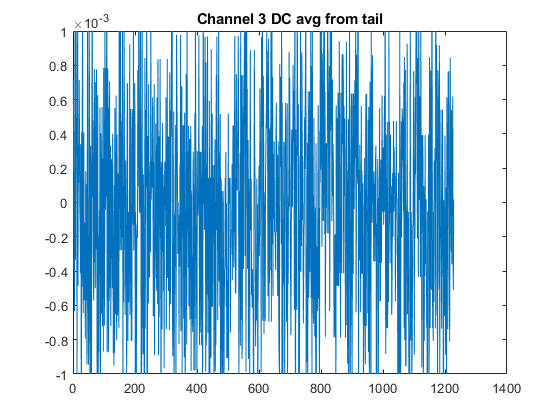

data33 = FBDCCh3.Ch3DataObj.rawDataDCRemoved;
% figure;plot(data3);title('Channel 3 truncated data')
% figure;plot(mean(data3,2));title('Channel 3 truncated data')
% figure;plot(mean(data2(1:200,:)))
% title('Channel 2 DC avg from start')
dataTemp33 = data33(end-25:end,:);
figure;plot(mean(dataTemp33));ylim([-0.001 0.001])
title('Channel 3 DC avg from tail')

mean(mean(dataTemp33))

ans = -3.7330e-05